## SIMULAÇÃO COMPUTACIONAL DE RECONSTRUÇÃO TOMOGRÁFICA POR RETROPROJEÇÃO FILTRADA

Neste código é possível fazer a reconstrução de 4 imagens:

1) Fantoma da cabeça Shepp-Logan. A imagem fantoma ilustra as imagens tomográficas do mundo real de cabeças humanas. A concha elíptica brilhante ao longo do exterior é análoga a um crânio e as muitas elipses internas são análogas a características cerebrais ou tumores.

2) Padrão SMPTE, denominado RP 133-1991, recomendado para testes de padrão de imagens médicas diagnósticas para monitores de vídeo, câmeras e impressoras.

3) A imagem correspondente à fatia de um abdomem de um cadáver humano masculino disponibilizado pelo projeto Visible Human Project

4) A imagem correspondente à fatia da cabeça de um cadáver humano masculino disponibilizado pelo projeto Visible Human Project

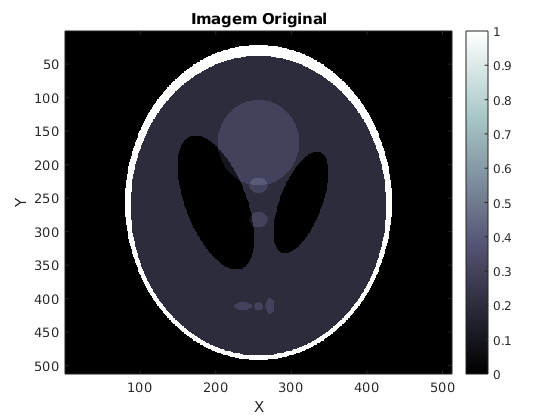

figure
colormap bone 

% Sheep-Logan phantom
imageData=phantom('Modified Shepp-Logan',512); % 512 specifies the number of rows and columns in the phantom image.

% Padrao SMTE
%imageData=double(imread('smpte.jpg'));

% Specimen from the Visible Human Male - Head subset
%imageData=double(imread('m_vm1125.t1.png'));

% Imagem Original
imagesc(imageData);
title('Imagem Original');
xlabel('X');
ylabel('Y');
colorbar

#### Ampliação e rotação da imagem

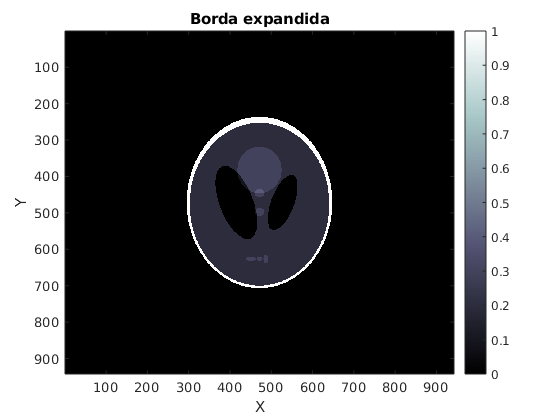

%Ampliar borda e preencher com zeros para evitar perda de dados ao
%rotacionar imagem
ampliaBorda        = ceil(norm(size(imageData)) - size(imageData)) + 2;
imageData_ampliada = padarray(imageData,ampliaBorda);

% Imagem Ampliada
imagesc(imageData_ampliada);
title('Borda expandida');
xlabel('X');
ylabel('Y');
colorbar

#### Definição das projeções e criação do SInograma

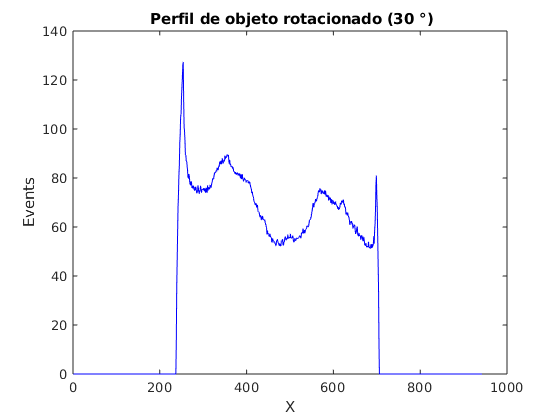

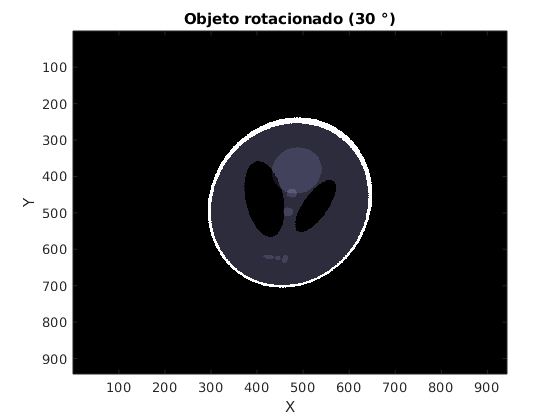

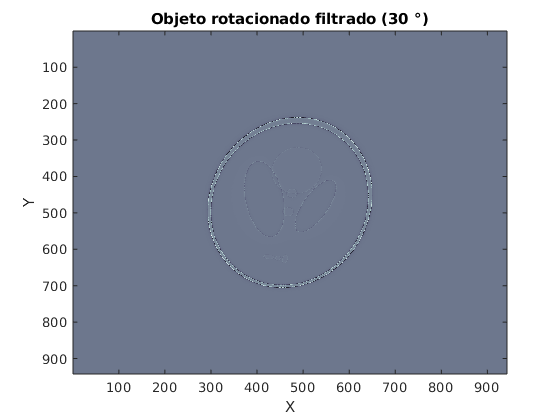

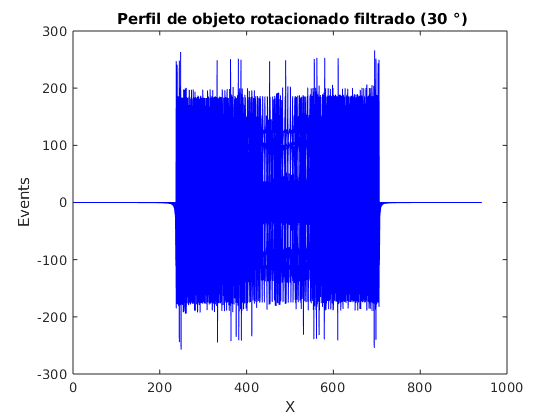

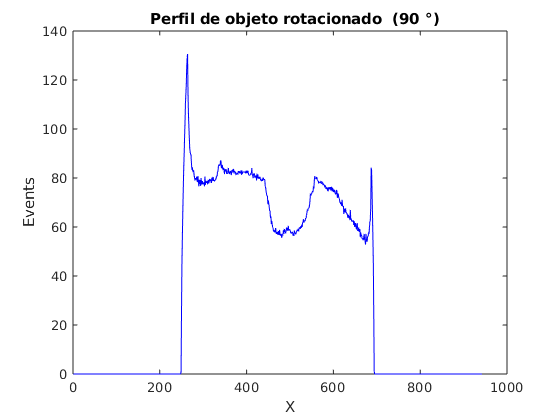

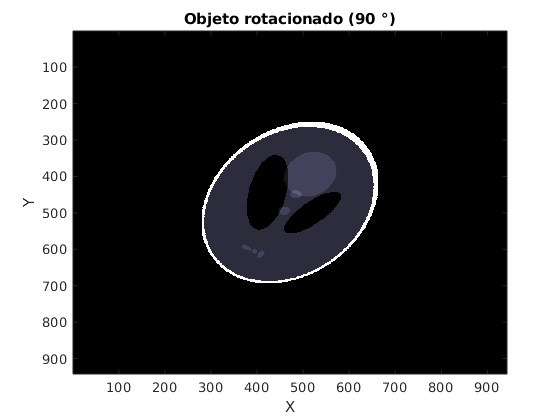

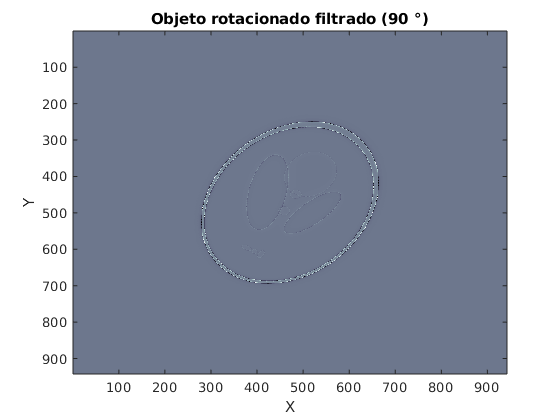

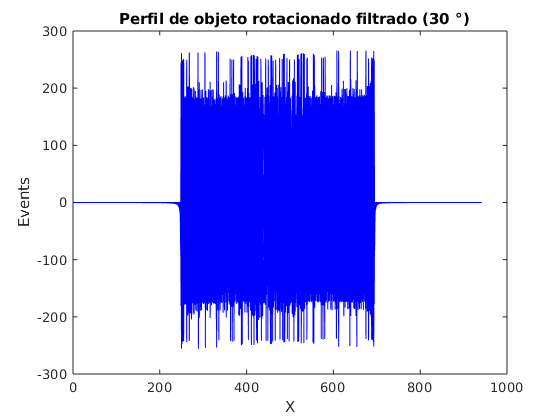



% Alguns parâmetros para definição dos ângulos do loop
freq = 3; % [1/degree]
thetas = 0:1/freq:180-1/freq;

% Definicao das projecoes e sinograma
numDeProjecoesAngulares  = length(thetas);
numDeProjecoesParalelas = size(imageData_ampliada,1);
sinograma = zeros(numDeProjecoesParalelas,numDeProjecoesAngulares);

% Loop sobre o os angulos
for angulo_rotacao = 1:length(thetas)
   
   % Rotacionar imagem
   tmpImage      = imrotate(imageData_ampliada,-thetas(angulo_rotacao),'nearest','crop');
   %imagesc(tmpImage);
   %drawnow
   
   % Pegando pontos especificos para plotar. Não faz parte do algoritimo
   if angulo_rotacao == 30;      
       
       %projecao sem filtro
       verticalProfile = sum(tmpImage, 2);
       [rows, columns] = size(tmpImage);
       plot_perfilVertical = plot(1:columns, verticalProfile, 'b-');
       title(' Perfil de objeto rotacionado (30 \circ)')
       xlabel('X');
       ylabel('Events');
       saveas(plot_perfilVertical,'./rotation30_profile_phantom.jpg')
       
       figure
       colormap bone 
       imagesc(tmpImage);
       title('Objeto rotacionado (30 \circ)');
       xlabel('X');
       ylabel('Y');
       
       %projecao sem filtro
       figure
       colormap bone
       reconstrucao2D = retroprojecaoFiltrada2D(tmpImage);
       imagesc(reconstrucao2D);
       title('Objeto rotacionado filtrado (30 \circ)');
       xlabel('X');
       ylabel('Y');
       
       figure
       colormap bone
       fperfilVertical = sum(reconstrucao2D, 2);
       [frows, fcolumns] = size(reconstrucao2D);
       fperfilVertical_plot = plot(1:columns, reconstrucao2D, 'b-');
       title(' Perfil de objeto rotacionado filtrado (30 \circ)')
       xlabel('X');
       ylabel('Events');
       %saveas(fperfilVertical_plot,'./rotation30_filtered_profile_phantom.jpg')        
   end
   
   if angulo_rotacao == 90; 
       %imwrite(tmpImage,'./rotation150_phantom.jpg');
       
       %projecao sem filtro
       verticalProfile = sum(tmpImage, 2);
       [rows, columns] = size(tmpImage);
       plot_perfilVertical = plot(1:columns, verticalProfile, 'b-');
       title('  Perfil de objeto rotacionado  (90 \circ)')
       xlabel('X');
       ylabel('Events');
       saveas(plot_perfilVertical,'./rotation90_profile_phantom.jpg')
       
       figure
       colormap bone 
       imagesc(tmpImage);
       title('Objeto rotacionado (90 \circ)');
       xlabel('X');
       ylabel('Y');
       
       %projecao com filtro
       figure
       colormap bone
       reconstrucao2D = retroprojecaoFiltrada2D(tmpImage);
       imagesc(reconstrucao2D);
       title('Objeto rotacionado filtrado (90 \circ)');
       xlabel('X');
       ylabel('Y');
       
       figure
       colormap bone
       fperfilVertical = sum(reconstrucao2D, 2);
       [frows, fcolumns] = size(reconstrucao2D);
       fperfilVertical_plot = plot(1:columns, reconstrucao2D, 'b-');
       title('  Perfil de objeto rotacionado filtrado (30 \circ)')
       xlabel('X');
       ylabel('Events');
   end
      
   if angulo_rotacao == 150; 
       %imwrite(tmpImage,'./rotation150_phantom.jpg');
       
       %projecao sem filtro
       verticalProfile = sum(tmpImage, 2);
       [rows, columns] = size(tmpImage);
       plot_perfilVertical = plot(1:columns, verticalProfile, 'b-');
       title('Perfil de objeto rotacionado (150 \circ)')
       xlabel('X');
       ylabel('Events');
       saveas(plot_perfilVertical,'./rotation150_profile_phantom.jpg')
       
       figure
       colormap bone 
       imagesc(tmpImage);
       title('Objeto rotacionado (150 \circ)');
       xlabel('X');
       ylabel('Y');
       
       %projecao com filtro
       figure
       colormap bone
       reconstrucao2D = retroprojecaoFiltrada2D(tmpImage);
       imagesc(reconstrucao2D);
       title('Objeto rotacionado filtrado (150 \circ)');
       xlabel('X');
       ylabel('Y');
       
       figure
       colormap bone
       fperfilVertical = sum(reconstrucao2D, 2);
       [frows, fcolumns] = size(reconstrucao2D);
       fperfilVertical_plot = plot(1:columns, reconstrucao2D, 'b-');
       title('  Perfil de objeto rotacionado filtrado (150 \circ)')
       xlabel('X');
       ylabel('Events');
   end
   
   % Preencher sinograma
   sinograma(:,angulo_rotacao) = sum(tmpImage,2);
   
end

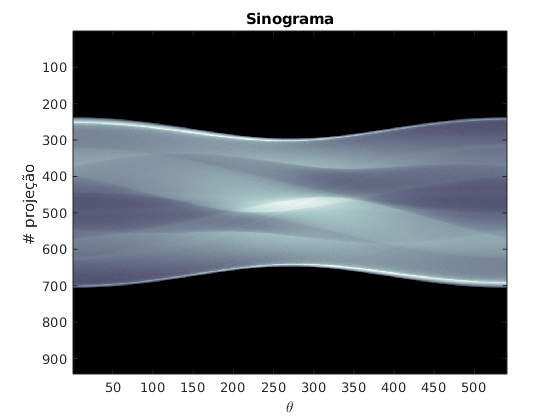


%sinograma = myButter(imageData_ampliada,thetas);
imagesc(sinograma)
title('Sinograma')
xlabel('\theta')
ylabel('# projeção ')

####      Retroprojeção simples (sem filtro)

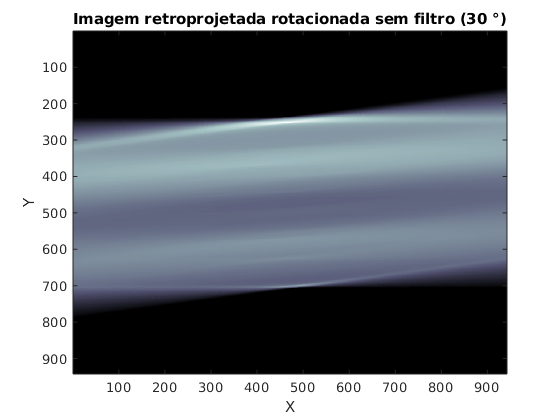

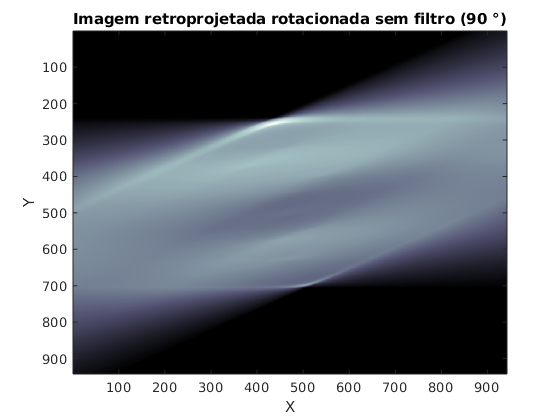

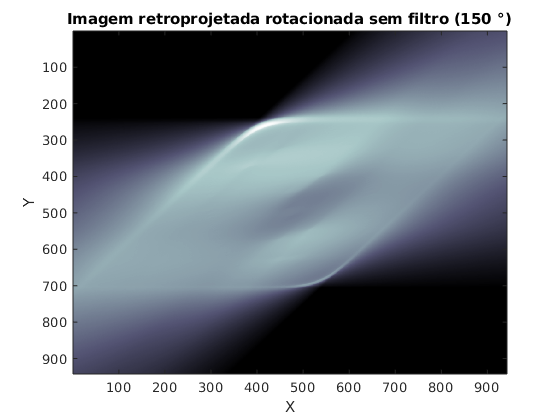

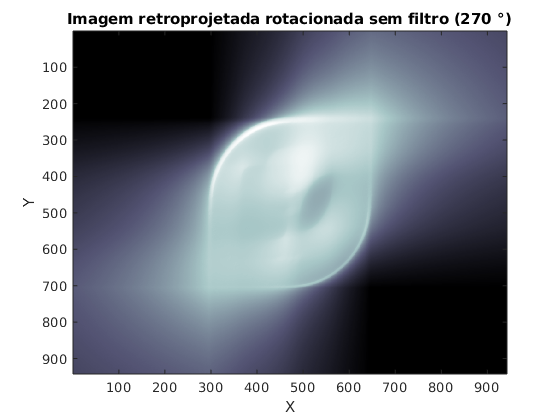

% Criar uma imagem para a retroprojeção, de mesmas dimendões do sinograma
numDeProjecoesParalelas = size(sinograma,1);
numDeProjecoesAngulares  = length(thetas); 
thetas = (pi/180)*thetas; % convert to radian
BPI = zeros(numDeProjecoesParalelas,numDeProjecoesParalelas);

% Setar coordenadas
midindex = floor(numDeProjecoesParalelas/2) + 1;
[xCoords,yCoords] = meshgrid(ceil(-numDeProjecoesParalelas/2):ceil(numDeProjecoesParalelas/2-1));

% Loop sobre cada projeção
for i = 1:numDeProjecoesAngulares
    rotCoords = round(midindex + xCoords*sin(thetas(i)) + yCoords*cos(thetas(i)));
    indices   = find((rotCoords > 0) & (rotCoords <= numDeProjecoesParalelas));
    newCoords = rotCoords(indices);
    
    % soma
    BPI(indices) = BPI(indices) + sinograma(newCoords,i)./numDeProjecoesAngulares;
    
   % Salvas imagens. Não faz arte do algoritimo 
   if i == 30;       
       figure
       colormap bone 
       imagesc(BPI);
       title('Imagem retroprojetada rotacionada sem filtro (30 \circ)');
       xlabel('X');
       ylabel('Y');
   end
   
   if i == 90; 
       figure
       colormap bone 
       imagesc(BPI);
       title('Imagem retroprojetada rotacionada sem filtro (90 \circ)');
       xlabel('X');
       ylabel('Y');
   end
      
   if i == 150; 
       figure
       colormap bone 
       imagesc(BPI);
       title('Imagem retroprojetada rotacionada sem filtro (150 \circ)');
       xlabel('X');
       ylabel('Y');
   end
   
    if i == 270; 
       figure
       colormap bone 
       imagesc(BPI);
       title('Imagem retroprojetada rotacionada sem filtro (270 \circ)');
       xlabel('X');
       ylabel('Y');
   end
    % visualization on the fly
    %imagesc(BPI)
    %drawnow
    
end

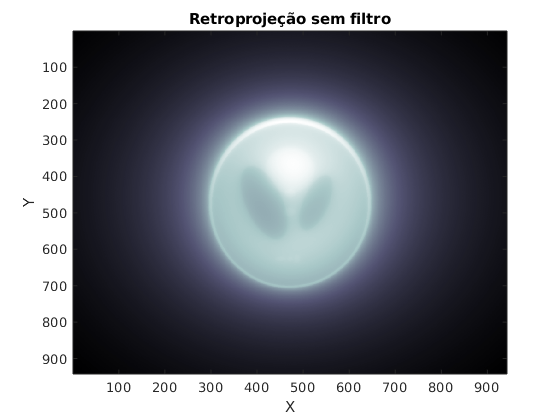


imagesc(BPI);
title('Retroprojeção sem filtro')
xlabel('X')
ylabel('Y')

####     Adicionando filtro

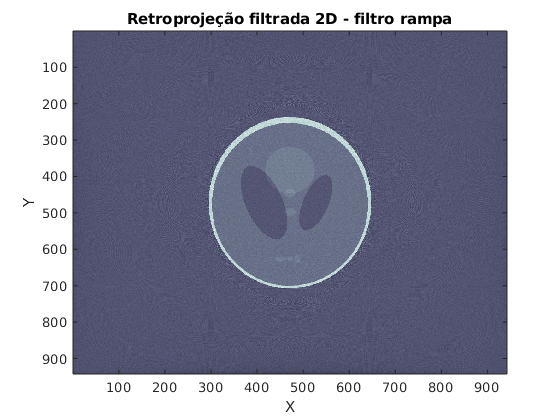

midindex = floor(size(BPI,1)/2) + 1;

% find the middle index of the projections
midindex = floor(size(BPI,1)/2) + 1;
% Preparar filtro para o dominio da frequência sem normalização
[xCoords,yCoords] = meshgrid(1 - midindex:size(BPI,1) - midindex);
filtroRampa2D      = sqrt(xCoords.^2 + yCoords.^2);
% Transformada 2D de Fourier
reconstrucao2D = fftshift(fft2(BPI));
% Aplicação do filtro
reconstrucao2D = reconstrucao2D .* filtroRampa2D;
%reconstrucao2D = reconstrucao2D .* butter(2,0.5,'low');
% Transformada Inversa 2D de Fourier
reconstrucao2D = real( ifft2( ifftshift(reconstrucao2D) ) );

imagesc(reconstrucao2D);
title('Retroprojeção filtrada 2D - filtro rampa')
xlabel('X')
ylabel('Y')

####     Alisamento de imagem

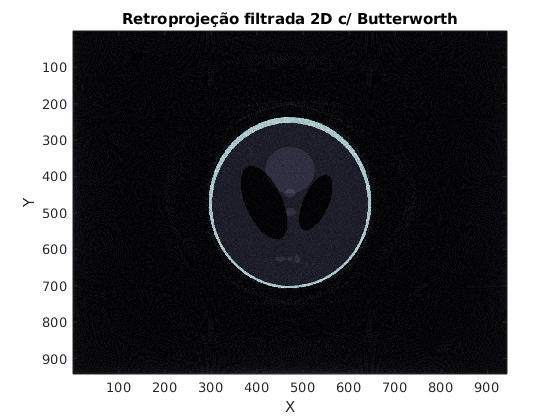

% Adicionando filtro Butterworth
[m n]=size(reconstrucao2D);
ButterData=abs(ifft2(ifftshift(myButter(m,n,2,3)).*fft2(reconstrucao2D))); 
imagesc(ButterData);
title('Retroprojeção filtrada 2D c/ Butterworth')
xlabel('X')
ylabel('Y')